## 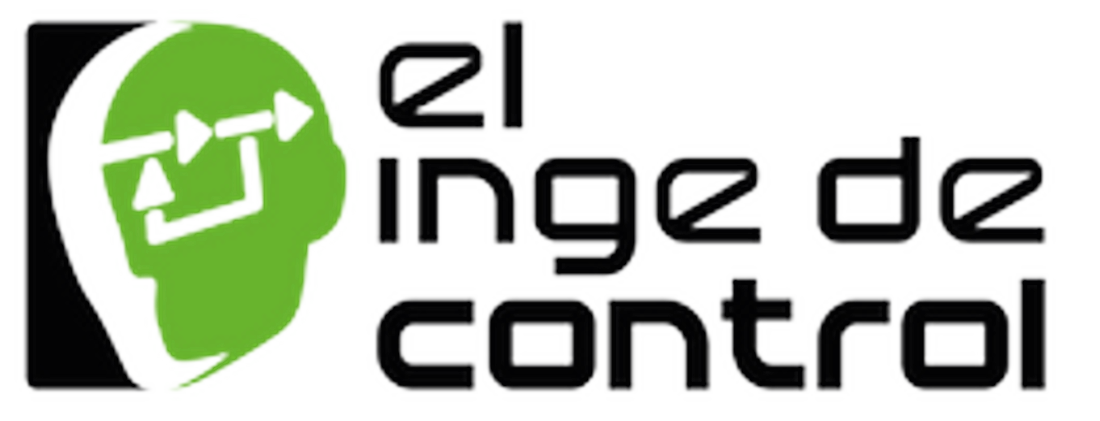

# **Taller: Control Robusto y Estocástico**

## Tema: Control ${\mathcal{H}}_{\infty }$de información completa

## Dr. Julio A. García Rodríguez

Ejercicio 01. $\mathcal{H}_2$

clc, clear all, close all

Set random seed for reproducibility

rng(1, 'twister')

Generate a random state-space system and transpose it. This command creates a 4-output, 5-input stable model and then takes its Hermitian conjugate. This operation yields a 5-output, 4-input unstable model

P = rss(3, 4, 5)';  % 3 states, 5 inputs, 4 outputs → transposed: 4 inputs, 5 outputs
pole(P)             % Confirm that P is unstable. All the poles are in the right half-plane.

ans =    0.5640 + 1.7159i
   0.5640 - 1.7159i
   0.0000 + 0.0000i


Display state-space matrices

A = P.A

A =     3.3542    1.4375    1.2156
  -16.3938   -6.9852   -5.5716
   18.4117    7.6794    4.7590


B = P.B

B =    -0.0660         0    0.3222   -0.7884
         0    0.4908         0   -0.5907
    0.6358   -0.6033         0    0.1551


C = P.C

C =    -1.9654   -1.2701         0
    2.0292         0    0.6037
    1.7813         0   -1.8651
   -1.0511         0    1.4022
         0   -0.2925         0


D = P.D

D =          0   -1.0443   -0.3456         0
         0    0.9262         0   -0.5581
         0         0    0.2589         0
         0    0.4259         0         0
         0   -0.2765   -1.8576         0


disp('Matrix A:'); disp(A);

Matrix A:
    3.3542    1.4375    1.2156
  -16.3938   -6.9852   -5.5716
   18.4117    7.6794    4.7590



disp('Matrix B:'); disp(B);

Matrix B:
   -0.0660         0    0.3222   -0.7884
         0    0.4908         0   -0.5907
    0.6358   -0.6033         0    0.1551



disp('Matrix C:'); disp(C);

Matrix C:
   -1.9654   -1.2701         0
    2.0292         0    0.6037
    1.7813         0   -1.8651
   -1.0511         0    1.4022
         0   -0.2925         0



disp('Matrix D:'); disp(D);

Matrix D:
         0   -1.0443   -0.3456         0
         0    0.9262         0   -0.5581
         0         0    0.2589         0
         0    0.4259         0         0
         0   -0.2765   -1.8576         0



Controllability and observability analysis

ctrbRank = rank(ctrb(A, B))

ctrbRank = 3

obsvRank = rank(obsv(A, C))

obsvRank = 3

Step Response

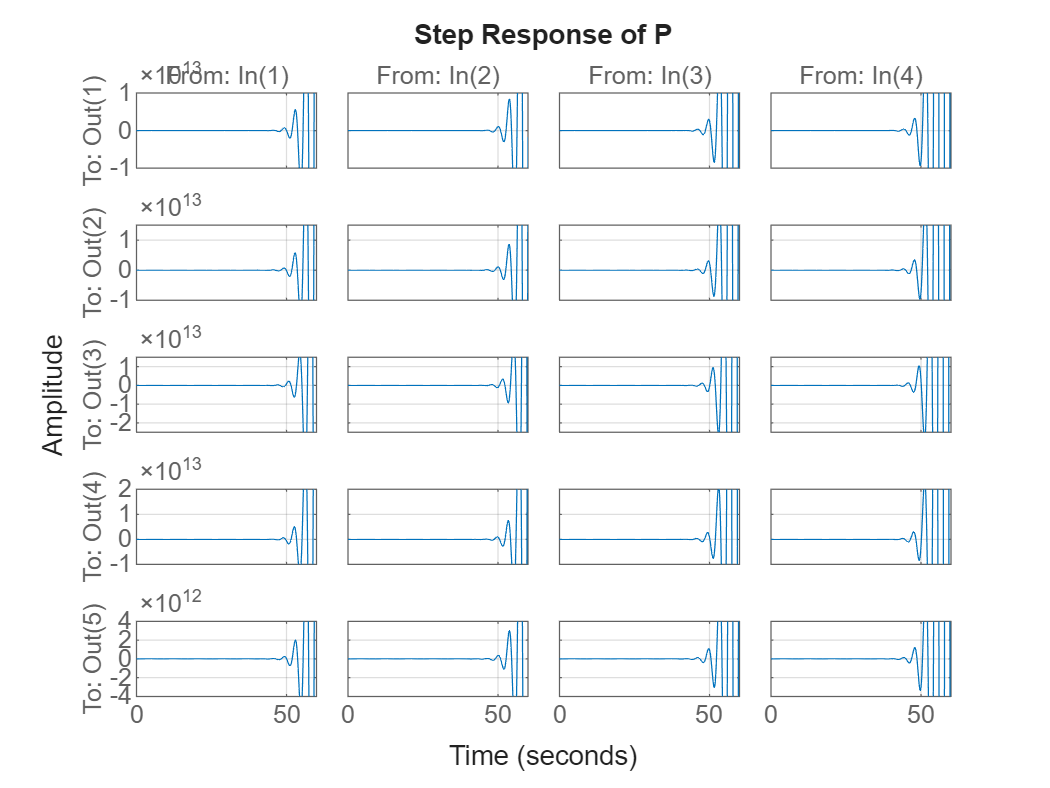

step(P)
title('Step Response of P');
grid on

Impulse response 

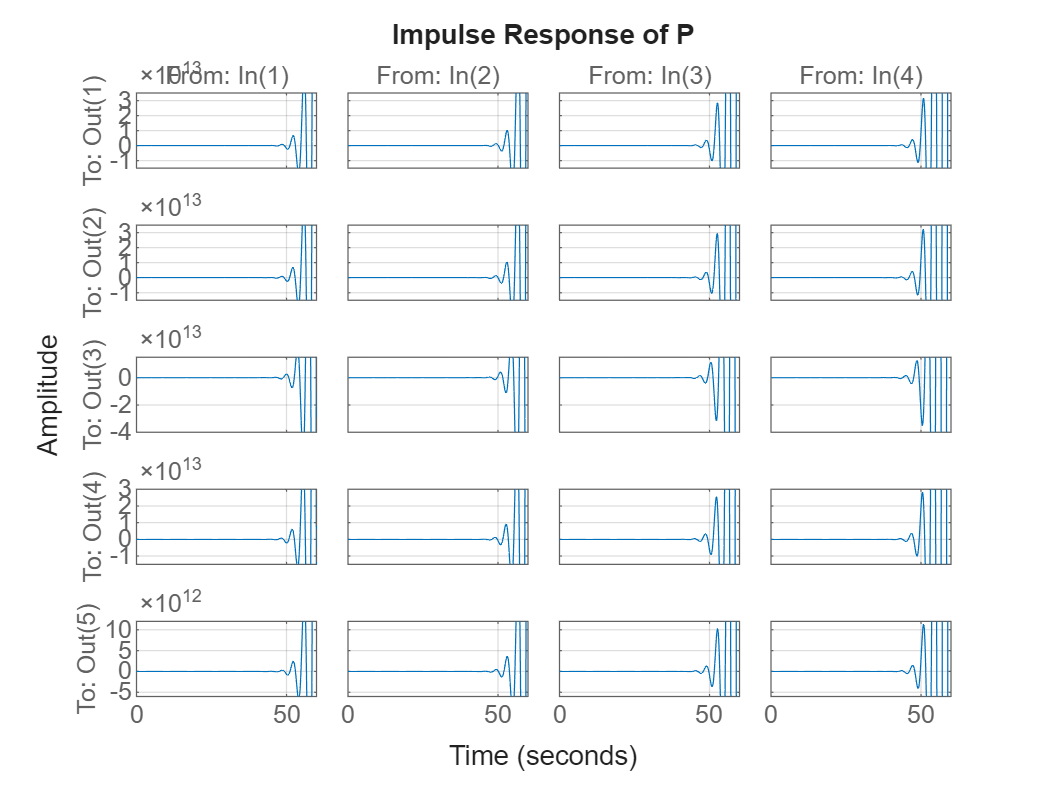

impulse(P)
title('Impulse Response of P');
grid on

Frequency response (Bode plot)

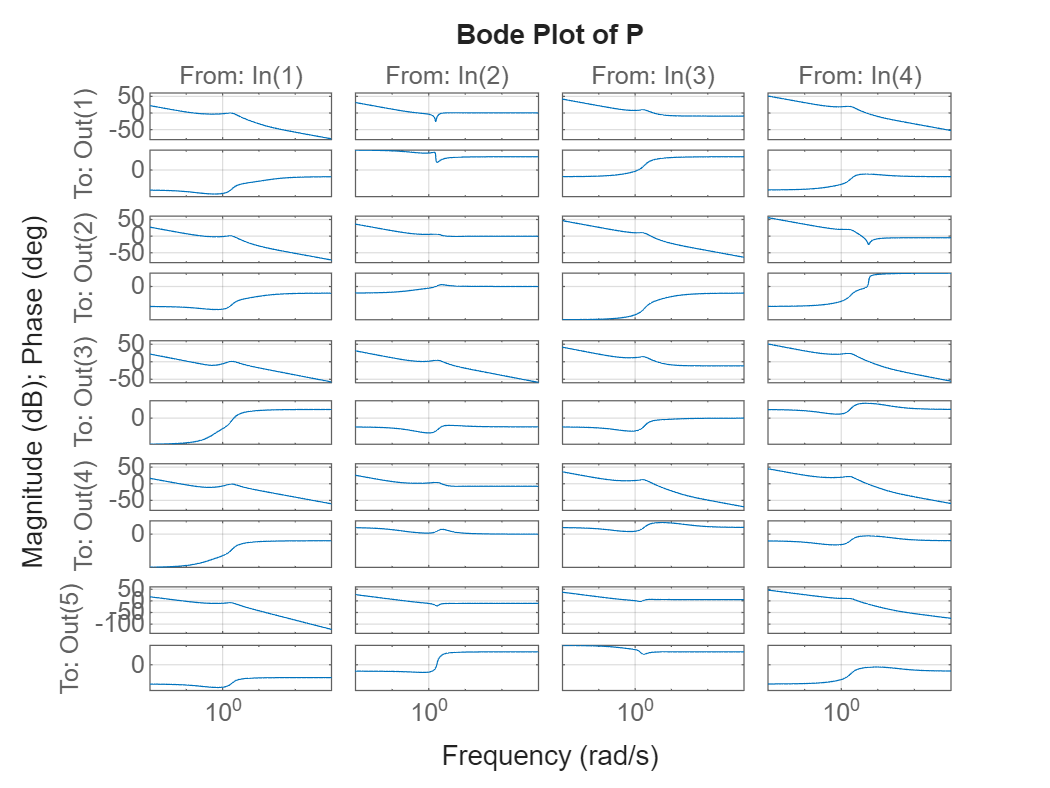

bode(P)
title('Bode Plot of P');
grid on

 Pole-zero map

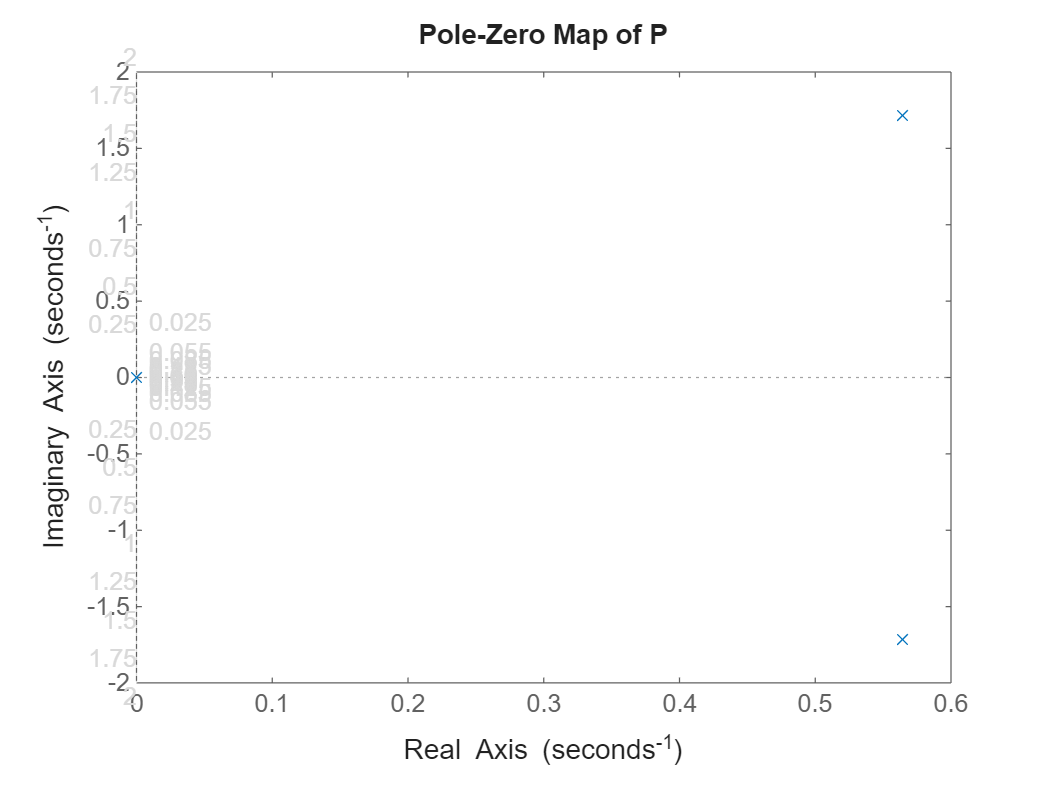

pzmap(P)
title('Pole-Zero Map of P');
grid on

Controller synthesis

[K,CL,GAM] = h2syn(P,2,1);

disp('Controller K:'); disp(K); K

Controller K:
  1×2 ss array with properties:

                A: [3×3 double]
                B: [3×2 double]
                C: [17.4564 3.8362 0.2168]
                D: [3.8973 -4.6066e-17]
                E: []
          Offsets: []
           Scaled: 0
        StateName: {3×1 cell}
        StatePath: {3×1 cell}
        StateUnit: {3×1 cell}
    InternalDelay: [0×1 double]
       InputDelay: [2×1 double]
      OutputDelay: 0
        InputName: {2×1 cell}
        InputUnit: {2×1 cell}
       InputGroup: [1×1 struct]
       OutputName: {''}
       OutputUnit: {''}
      OutputGroup: [1×1 struct]
            Notes: [0×1 string]
         UserData: []
             Name: ''
               Ts: 0
         TimeUnit: 'seconds'
     SamplingGrid: [1×1 struct]


K =
 
  A = 
           x1      x2      x3
   x1  -7.305  -1.479  -3.096
   x2   -36.6  -9.721   7.501
   x3   27.13   8.471  -3.227
 
  B = 
            u1       u2
   x1 

disp('Closed-Loop CL:'); disp(CL);

Closed-Loop CL:
  3×3 ss array with properties:

                A: [6×6 double]
                B: [6×3 double]
                C: [3×6 double]
                D: [3×3 double]
                E: []
          Offsets: []
           Scaled: 0
        StateName: {6×1 cell}
        StatePath: {6×1 cell}
        StateUnit: {6×1 cell}
    InternalDelay: [0×1 double]
       InputDelay: [3×1 double]
      OutputDelay: [3×1 double]
        InputName: {3×1 cell}
        InputUnit: {3×1 cell}
       InputGroup: [1×1 struct]
       OutputName: {3×1 cell}
       OutputUnit: {3×1 cell}
      OutputGroup: [1×1 struct]
            Notes: [0×1 string]
         UserData: []
             Name: ''
               Ts: 0
         TimeUnit: 'seconds'
     SamplingGrid: [1×1 struct]



disp('Gamma:'); disp(GAM);

Gamma:
   Inf



pole(CL)
Ak=K.A;
Bk=K.B;
Ck=K.C;
Dk=K.D;